Initialize Matlab

clear; clc; close all;
set(0,'defaultAxesFontName','Times')
set(0,'defaultTextFontName','Times')
set(0,'defaultAxesFontSize',18)
set(0,'defaultTextFontSize',18)
set(0,'defaulttextinterpreter','latex')
set(0,'defaultLineLineWidth',2)

Vehicle Parameters

m = 720; i = 300; lr = 1.15; lf = 2.3;
df = 0.8 * m * 9.81 / 2.0;
dr = 0.8 * m * 9.81 / 2.0;
bf = 1.0; br = 1.0;
cf = 1.25; cr = 1.25;
latteral_acc_max = 1.5;
longitudinal_acc_max = 1;

Load Track Data

 "Spielberg";

data = readtable("tracks/"+ans + "_track.csv");
x_center = data.x_X_m;
y_center = data.y_m;

% global center_line
center_line = [x_center, y_center]';

% Compute left and right margins
right_margin = data.w_tr_right_m;
left_margin = data.w_tr_left_m;
inner_limit = zeros(2, size(center_line, 2));
outer_limit = zeros(2, size(center_line, 2));
previous = center_line(:, end);
right_rot = [cosd(-90) -sind(-90); sind(-90) cosd(-90)];
left_rot = [cosd(90) -sind(90); sind(90) cosd(90)];
for i = 1:size(center_line, 2)
    direction = normalize((-previous + center_line(:, i))')';
    
    inner_limit(:, i) = center_line(:, i) + right_rot * direction * right_margin(i);
    outer_limit(:, i) = center_line(:, i) + left_rot * direction * left_margin(i);

    previous = center_line(:, i);
end

% Convert Eucledian Coordinate to Curvilinear
refPathObj = referencePathFrenet(center_line'); center_line = refPathObj.SegmentParameters;

Build Controller

% Define State and Input Sets
X_set = Polyhedron('lb', -[0; 10; pi/2; 5; pi/6; 0.16; 0.16],'ub', [100; 10; pi/2; 5; pi/6; 0.16; 0.16]);
U_set = Polyhedron('lb', -[12; 0.3], 'ub', [12; 0.3]);

% System and Simulation Properties
n_u = 2; n_x = 7; 
dt = 0.05; N = 20;
x_ = sdpvar(repmat(n_x,1,N+1),ones(1,N+1));
u_ = sdpvar(repmat(n_u,1,N+1),  ones(1,N+1));
du_ = sdpvar(repmat(n_u,1,N),  ones(1,N));
% curv_ = sdpvar(repmat(1,1,N),  ones(1,N));

% Define weight matrices
% Q = diag([-1.2e-4; -9.704; 0; 3.5e-5; -0.154; 0; 0]);
Q = diag([-1; 0.1; 0; 1; 0.01; 0; 0]);
R = diag([5, 10]);
q = [1.007; 0.187; 0; 6.1e-7; -0.032; 0; 0];

curvature(s, center_line)

ans = 4.0848e-07

% deltaT = 0.05;
% car = Simulation(center_line, 196, 300, 0.638, 0.902, 100000, deltaT, dt);
clc
% Initialize vehicle's position
x0 = [0.01; 0; 0; 0; 0; 0; 0];
s = 0;
X = center_line(1,1); Y = center_line(1,2);
psi = -0.5 * (center_line(end, 3) + center_line(1, 3));
y = [X; Y; psi];

time_series = [0];
% output = car.x_;
u = [0;0];
input = [u];

i = 1;
% while x0(5) < center_line(end, 6)
while i < 20
    % define controller objective and constraints
    constraints = []; objective = 0;
    curv = curvature(s, center_line);
    [A, B] = linearSS([x0(1),x0(2),x0(5), curv,x0(4),u(2)], dt);
    for k = 1:N
%         objective = objective - x_{k}' * Q * x_{k} + q' * x_{k};
%         objective = objective - ((x_{k}(1)*cos(x_{k}(5))-x_{k}(2)*sin(x_{k}(5)))/(1-car.curvature(car.x_(5))*x_{k}(4)))^2;
        objective = objective + x_{k}' * Q * x_{k} + du_{k}' * R * du_{k};        
        constraints = [constraints, x_{k+1} == A * x_{k} + B * u_{k+1}];
        constraints = [constraints, u_{k+1} == u_{k} + du_{k}];
        constraints = [constraints, U_set.A * u_{k} <= U_set.b];
        constraints = [constraints, X_set.A * x_{k} <= X_set.b];


    end
    % Build Controller and solve
    inputs  = {x_{1}, u_{1}};
    outputs = du_(1);
    controller = optimizer(constraints,objective,sdpsettings('solver','quadprog','verbose',0),inputs,outputs);
    [delta_u, flag] = controller(x0, u);
    if flag ~= 0
        i
        flag
    end
    u = u + delta_u;
    [x0, s, X, Y, psi] = step(x0, u, curv, X, Y, psi, dt);
    y = [y, [X; Y; psi]];
    output = [output, [s; x0]];
    input = [input, u];
    i = i+1;
    time_series = [time_series, i * dt];
%     x0 = [car.x_(1);car.x_(2);car.x_(3);car.x_(6);car.x_(4); a_f; a_r];
end

i = 1

flag = 1

توش کاری بعدا پاک کن

% save('Reference', 'output', 'input')
data = readtable("tracks\Spielberg.csv");
x_center = data.x_X_m;
y_center = data.y_m;

% global center_line
y = [x_center, y_center]';

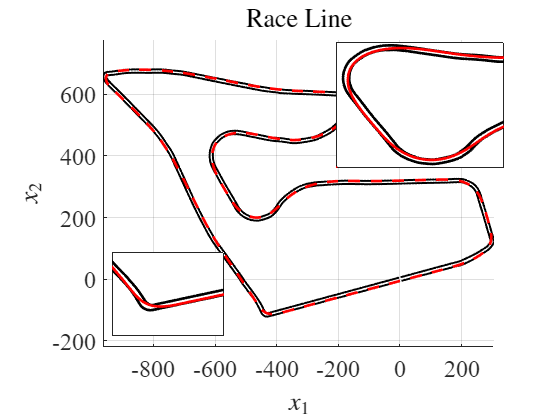

figure
hold on; grid on;
plot(inner_limit(1, :), inner_limit(2, :), '-k', 'LineWidth',1.5);
plot(outer_limit(1, :), outer_limit(2, :), '-k', 'LineWidth',1.5);
plot(y(1, :), y(2, :), '--r');
axis equal
title('Race Line')
xlabel('$x_1$')
ylabel('$x_2$')
grid on
axes('position',[.6 .6 .3 .3])
box on % put box around new pair of axes
plot(inner_limit(1, :), inner_limit(2, :), '-k'); hold on;
plot(outer_limit(1, :), outer_limit(2, :), '-k');
plot(y(1, :), y(2, :), '-r');
set(gca,'XTick',[], 'YTick', [])
xlim([-630 -340])
ylim([180 490])
axes('position',[.2 .2 .2 .2])
box on % put box around new pair of axes
plot(inner_limit(1, :), inner_limit(2, :), '-k'); hold on;
plot(outer_limit(1, :), outer_limit(2, :), '-k');
plot(y(1, :), y(2, :), '-r');
set(gca,'XTick',[], 'YTick', [])
xlim([-500 -300])
ylim([-180 10])

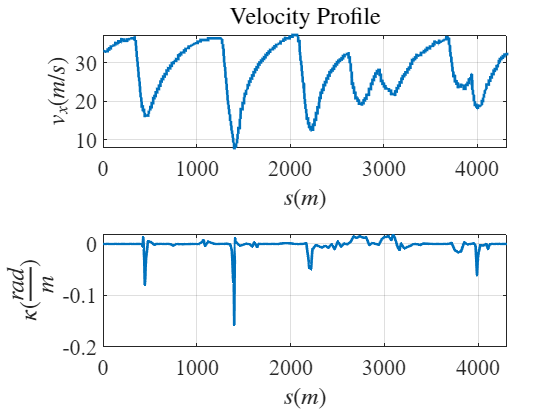

data = readtable('Default Dataset.csv');
output = [data.Var1'; data.Var2'];
figure
subplot(2,1, 1)
stairs(output(1, :), output(2, :), 'LineWidth',2); grid on;
xlabel('$s (m)$')
ylabel('$v_x (m/s)$')
title('Velocity Profile')
xlim([0, output(1, end)]);
subplot(2,1, 2)
plot(center_line(:, 6), center_line(:, 4)); grid on;
xlabel('$s (m)$')
ylabel('$\kappa (\frac{rad}{m})$')
xlim([0, center_line(end, 6)]);

Select Velocity:

velocity =8;

Select Simulation Duration:

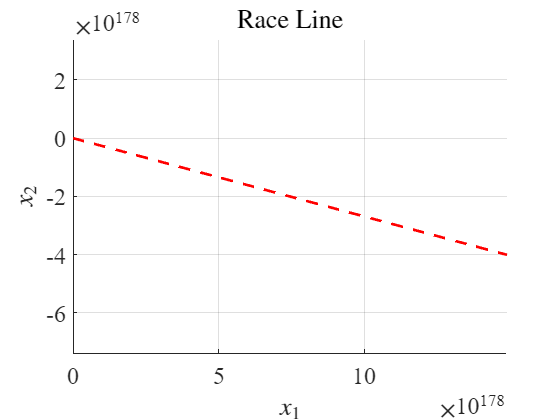

time =7;
% Simulation parameters
dt = 0.01;
x0 = [0.01; 0; 0; 0; 0; 0; 0];

time_series = 0:dt:60*time;
x0 = [0.01; 0; 0; 0; 0; 0; 0];
input = zeros(2, size(time_series, 1));
s = 0;
X = center_line(1,1); Y = center_line(1,2);
psi = -0.5 * (center_line(end, 3) + center_line(1, 3));
y = [X; Y; psi];

K_psi = -0.01;
K_v = 2;

for i = 1:length(time_series)
    curv = curvature(s, center_line);
%     u = [K_v * (velocity/3.6 - x0(1)), K_psi * (x0(4))];
u = [-0.5; 0];
    [x0, s, X, Y, psi] = step(x0, u, curv, X, Y, psi, dt);
    y = [y, [X; Y; psi]];
    input(:, i) = u;
    
end
figure
hold on; grid on;
plot(inner_limit(1, :), inner_limit(2, :), '-k', 'LineWidth',1.5);
plot(outer_limit(1, :), outer_limit(2, :), '-k', 'LineWidth',1.5);
plot(y(1, :), y(2, :), '--r');
axis equal
title('Race Line')
xlabel('$x_1$')
ylabel('$x_2$')
grid on

function [A, B] = linearSS(param, Ts)
    %% Linearized approximation of vehicle based on current parameters
    % param = [v_x, v_y, e_theta, kappa, e_y, delta] 
    % x = [vx, vy, omega, e_y, e_theta, alpha_f, alpha_r] is state
    % u = [a_r, delta] is input.

    % physicla properties
    g = 9.81; mu = 1.4; lf = 0.902; lr = 0.638;
    m = 196; I = 93;
    df = 8.255; bf = 6.1; dr = 8.255; br = 6.1;
    cda = 1.64; d = 2.3;
    cf = 1.6; cr = 1.6; rho = 1.225; w = 1.45;
    
    % linearized A
    a11 = 1 + (-mu * g/param(1) - rho * cda * param(1) / (2*m)) * Ts;
    a12 = cf * sin(param(6)) * Ts / (m * param(1));
    a13 = ( (cf * lf * sin(param(6))) / (m * param(1)) + param(2)) * Ts;
    a22 = 1 - (cr + cf * cos(param(6))) / (m * param(1)) * Ts;
    a23 = ( - param(1)) * Ts;
    a32 = - (cf * lf * cos(param(6)) - lr * cr) / (I * param(1)) * Ts;
    a33 = 1 - (cf * lf^2 * cos(param(6)) + lr^2 * cr) / (I * param(1)) * Ts;
    a51 = param(4) / (1 - param(5) * param(4)) * Ts;
    a52 = param(4) / (1 - param(5) * param(4)) * sin(param(3)) * Ts;
    a53 = Ts; a42 = cos(param(3)) * Ts;
    a45 = param(1) * Ts; a62 = -1 / (param(1) * Ts); a63 = -lf / (param(1) * Ts);
    a72 = -1 / (param(1) * Ts); a73 = lr / (param(1) * Ts);
    
    % State Space matrices
    A = [a11, a12, a13, 0, 0, 0, 0;
        0, a22, a23, 0, 0, 0, 0;
        0, a32, a33, 0, 0, 0, 0;
        0, a42, 0, 1, a45, 0, 0;
        -a51, a52, a53, 0, 1, 0, 0;
        0, a62, a63, 0, 0, 0, 0;
        0, a72, a73, 0, 0, 0, 0];

    B = [-sin(param(6)) * cf / m, 1;
        cos(param(6)) * cf / m, 0;
        cos(param(6)) * cf * lf, 0;
        0, 0;
        0, 0;
        1/Ts, 0;
        0, 0];

end

function [x_next, s, X, Y, psi] = step(x, u, curv, X, Y, psi, dt)
    % physicla properties
    g = 9.81; mu = 1.4; lf = 0.902; lr = 0.638;
    m = 196; I = 93;
    df = 8.255; bf = 6.1; dr = 8.255; br = 6.1;
    cda = 1.64; d = 2.3;
    cf = 1.6; cr = 1.6; rho = 1.225; w = 1.45;

    alpha_f = u(2) - atan(x(2)/x(1) - lf * x(3)/x(1));
    alpha_r = - atan(x(2)/x(1) + lr * x(3) / x(1));
    Fyf = df * sin(cf * atan(bf * alpha_f));
    Fyr = dr * sin(cr * atan(br * alpha_r));
    Fdf = mu * g * m + 0.5 * rho * cda * x(1)^2;
    x_next = x(1:5, 1) + dt * ...
              [u(1) + (-Fyf * sin(u(2)) - Fdf) / m + x(3) * x(2);
              (Fyf * lf * cos(u(2)) - Fyr * lr) / m - x(3) * x(1);
              (Fyf * lf * cos(u(2)) - Fyr * lr) / I;
              x(1) * sin(x(5)) + x(2) * cos(x(5));
              x(3) - (x(1) * cos(x(5)) - x(2) * sin(x(5))) / (1 - x(4) * curv) * curv];
    x_next = [x_next; alpha_f; alpha_r];
    s = (x(1) * cos(x(5)) - x(2) * sin(x(5))) / (1 - curv * x(4));
    psi = psi + dt * x(3);
    X = X + dt * (x(1) * cos(psi) - x(2) * sin(psi));
    Y = Y + dt * (x(1) * sin(psi) + x(2) * cos(psi));
end

function kappa = curvature(s, center_line)
    s = rem(s,center_line(end,6));
    i = 1;
    while center_line(i, 6) < s
        i = i+1;
    end
    if i == 1
        kappa = 0.5 * (center_line(end, 4) + center_line(i, 4));
    else
        kappa = 0.5 * (center_line(i-1, 4) + center_line(i, 4));
    end
end